# Project: Find Optimal Buying-low Selling-high Strategy for mean-reverting stock

## Yida Chen

## Simulate the Stock Price with Brownian Motion:

The stock price is $S\left(t\right)\;=e^{X\left(t\right)}$ where $X\left(t\right)$ is governed by the differential equation below:


$$\textrm{dX}\left(t\right)=\lambda \left(\mu -X\left(t\right)\right)\textrm{dt}+\sigma \;\textrm{dW}\left(t\right)$$


$\lambda$ = Speed of mean reversion

$\mu$ = Long run mean

$\sigma$ = Volatility of the process

clf;
clear;

NSample = 100;
N_T = 100;
T = 100;
t0=0;

[TProcess, BProcess] = BrownMotion(NSample, t0, 0, T, N_T);

t0=0;
y0 = [2];
h = (T - t0) / (N_T - 1);


stock_prices = [];

for k=1:NSample
    w_diff = diff(BProcess(:, k));
%     w_diff = normrnd(0, sqrt(h), N_T-1);
    x_prime = @(t, y) 0.8 * (2 - y(1)) + 0.5 * (w_diff(int32(t / h) + 1));
    f = {x_prime};
    
    [ymat, t] = EulerSystem(f, t0, y0, T, N_T);
    stock_prices = cat(2, stock_prices, exp(ymat(:, 1)));
end

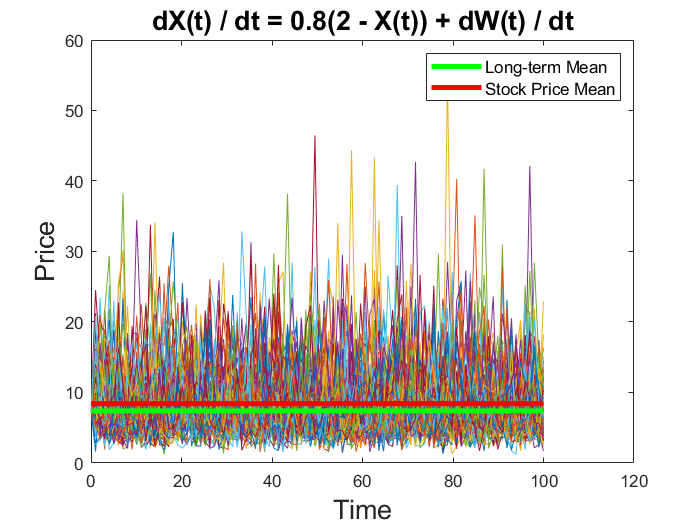

clf;
for k=1:NSample
    plot(t, stock_prices(:, k))
    hold on
end
p(1) = plot(t, ones(length(t), 1) * exp(2),'g','LineWidth',3, 'DisplayName', "Long-term Mean");
p(2) = plot(t, ones(length(t), 1) * mean(mean(stock_prices)),'r','LineWidth',3, 'DisplayName', "Stock Price Mean");
title("dX(t) / dt = 0.8(2 - X(t)) + dW(t) / dt",'FontSize', 16)
xlabel("Time", 'FontSize', 16)
ylabel("Price", 'FontSize', 16)
legend(p, 'FontSize', 10)
hold off

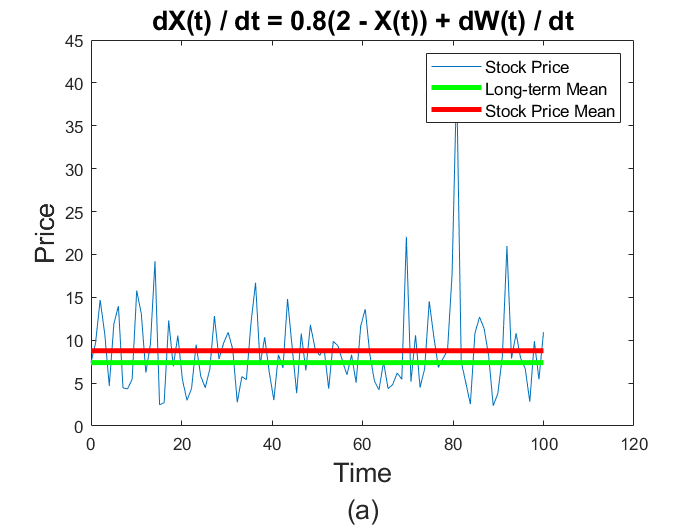

clf;
plot(t, stock_prices(:, 2))
hold on
plot(t, ones(length(t), 1) * exp(2),'g','LineWidth',3)
plot(t, ones(length(t), 1) * mean(stock_prices(:, 2)),'r','LineWidth',3)
hold off
title("dX(t) / dt = 0.8(2 - X(t)) + dW(t) / dt",'FontSize', 16)
xlabel({"Time", "(a)"}, 'FontSize', 16)
ylabel("Price", 'FontSize', 16)
legend("Stock Price", "Long-term Mean", "Stock Price Mean",'FontSize', 10)

## Global Optimization

Calculate the reward over multiple possible trends of stock prices given the same initial conditions.

b0 = 5

b0 = 5

s0 = 18

s0 = 18

reward =     8.2116    8.7610    8.6558    8.6950    8.6352    8.6499    8.6246    8.6232    8.6883    8.7301    8.6685    8.8970    8.6641    8.8191    8.7220    8.7860    8.6982    8.8445    8.6888    8.8125    8.8429    8.8415    8.8312    8.8462    8.8252    8.7974    8.8205    8.7401    8.7982    8.7203    8.9022    8.7912    8.8431    8.8422    8.8206    8.8357    8.8647    8.7889    8.8036    8.8052    8.8381    8.8166    8.8850    8.8196    8.8830    8.8198    8.8767    8.8088    8.8768    8.8070


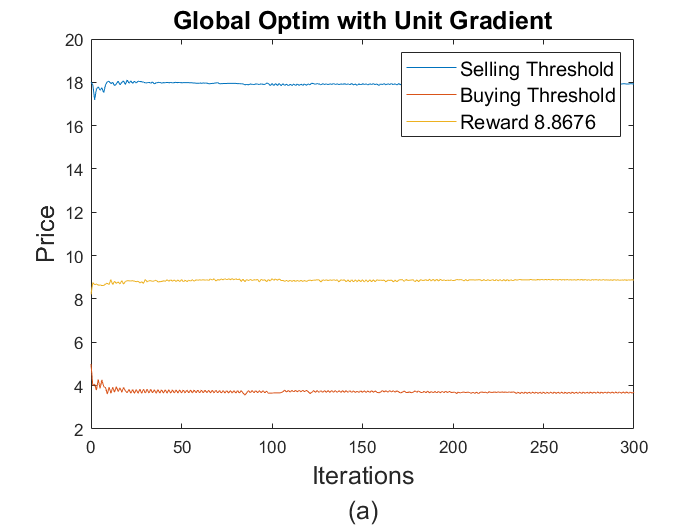

reward =     8.2116    8.5912    8.3094    8.6510    8.7876    8.6971    8.7382    8.7012    8.7205    8.7345    8.7466    8.7738    8.7797    8.7977    8.7645    8.7867    8.7521    8.8044    8.7418    8.6598    8.7006    8.7162    8.7408    8.7961    8.7416    8.7953    8.7424    8.7946    8.7344    8.7897    8.7722    8.7891    8.7728    8.7886    8.7733    8.7881    8.7621    8.7847    8.7982    8.7792    8.7986    8.7789    8.7989    8.7785    8.7992    8.7782    8.7996    8.7779    8.7912    8.7757


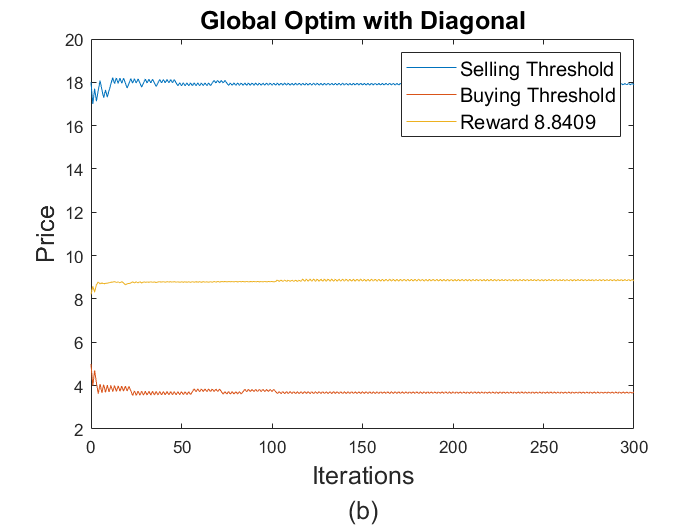

reward =     8.2116    8.7547    8.7533    8.7500    8.8050    8.7566    8.7969    8.7356    8.7958    8.7346    8.8223    8.6110    8.8096    8.6212    8.7951    8.6292    8.7854    8.6373    8.7795    8.6428    8.7745    8.7941    8.6790    8.7901    8.6668    8.7936    8.6636    8.7967    8.7968    8.7945    8.7989    8.8351    8.7177    8.8328    8.7200    8.8306    8.7220    8.8287    8.7858    8.8305    8.7841    8.8322    8.7825    8.8337    8.7810    8.8352    8.7796    8.8365    8.8241    8.8355


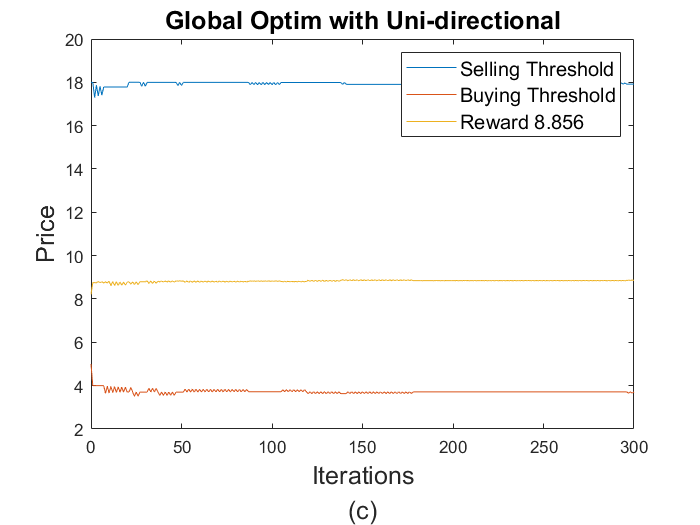

num_iter = 300;

rewards = {};
s_s = {};
b_s = {};
strategis = ["Adaptive Gradient", "Unit Gradient", "Diagonal", "Uni-directional"];
x_labels = ["0", "(a)", "(b)", "(c)"];

for mode=1:3
    s = [];
    b = [];
    reward = [];
    b(1) = b0;
    s(1) = s0;
    for iter=1:num_iter    
        c = (iter) ^ (-1/2);
        reward(iter) = TransactionReward(stock_prices, b(iter), s(iter), T);
        
        incre_b = b(iter) + c;
        reward_incre_b = TransactionReward(stock_prices, incre_b, s(iter), T);
        
        decre_b = b(iter) - c;
        reward_decre_b = TransactionReward(stock_prices, decre_b, s(iter), T);
        
        incre_s = s(iter) + c;
        reward_incre_s = TransactionReward(stock_prices, b(iter), incre_s, T);
        
        decre_s = s(iter) - c;
        reward_decre_s = TransactionReward(stock_prices, b(iter), decre_s, T);
        
        gradient_b = (reward_incre_b - reward_decre_b) / (2 * c);
        gradient_s = (reward_incre_s - reward_decre_s) / (2 * c);
        
        mag = sqrt(gradient_b ^ 2 + gradient_s ^ 2);
        
        [next_b, next_s] = update_bs(b(iter), s(iter), ...
            gradient_b, gradient_s, ...
            iter, c, mode);
        
        b(iter + 1) = next_b;
        s(iter + 1) = next_s;
        
        change = sqrt((b(iter + 1) - b(iter))^2 + (s(iter + 1)- s(iter))^2);
        if iter > 1 && change < 0.001
            break
        end
    end
    reward(iter + 1) = TransactionReward(stock_prices, b(iter + 1), s(iter + 1), T)
    
    figure()
    plot(linspace(0, length(reward) - 1, length(reward)), s)
    hold on
    plot(linspace(0, length(reward) - 1, length(reward)), b)
    plot(linspace(0, length(reward) - 1, length(reward)), reward)
    legend("Selling Threshold", "Buying Threshold", "Reward" + " " + string(reward(end)), "FontSize", 12)
    title("Global Optim with " + strategis(mode + 1), "FontSize", 15)
    hold off
    rewards{mode + 1} = reward;
    s_s{mode + 1} = s;
    b_s{mode + 1} = b;
    ylabel("Price", "FontSize", 15)
    xlabel({"Iterations", x_labels(mode + 1)}, "FontSize", 15)
end

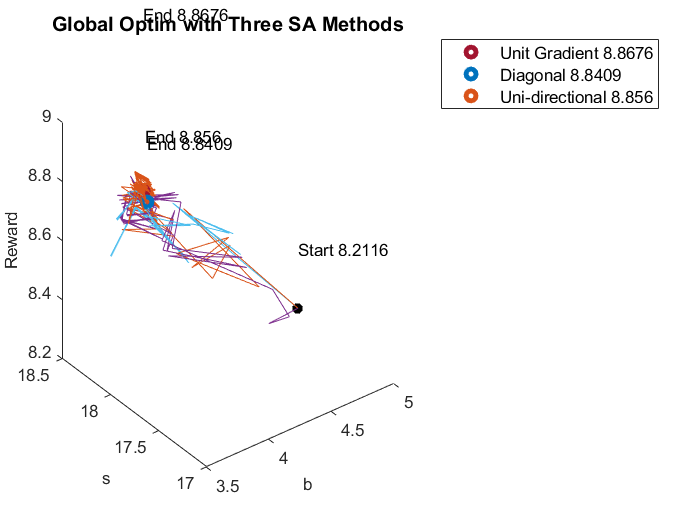

clf;
for i=2:4
    b = b_s{i};
    s = s_s{i};
    reward = rewards{i};
    plot3(b(1), s(1), reward(1), "*black", "linewidth", 3)
    hold on
    plot3(b, s, reward)
    hold on
    if i == 2
       text(b(end), s(end), reward(end) + 0.6, append('End ', string(reward(end)))) 
    else
       text(b(end), s(end), reward(end) + 0.2, append('End ', string(reward(end)))) 
    end
end
text(b_s{i}(1), s_s{i}(1), rewards{i}(1) + 0.2, append('Start ', string(rewards{i}(1))))

p = [];
for i=2:4
    b = b_s{i};
    s = s_s{i};
    reward = rewards{i};
    p(i-1) = plot3(b(end), s(end), reward(end), "o", "linewidth", 3, 'DisplayName', strategis(i) + " " + string(reward(end)));
end

xlabel("b", "FontSize", 10)
ylabel("s", "FontSize", 10)
zlabel("Reward", "FontSize", 10)
title("Global Optim with Three SA Methods", "FontSize", 12)

legend(p, "FontSize", 10)

## Before Optimizing:

What we gain by using the initial buying and selling threshold to perform one transaction on one of the stocks.

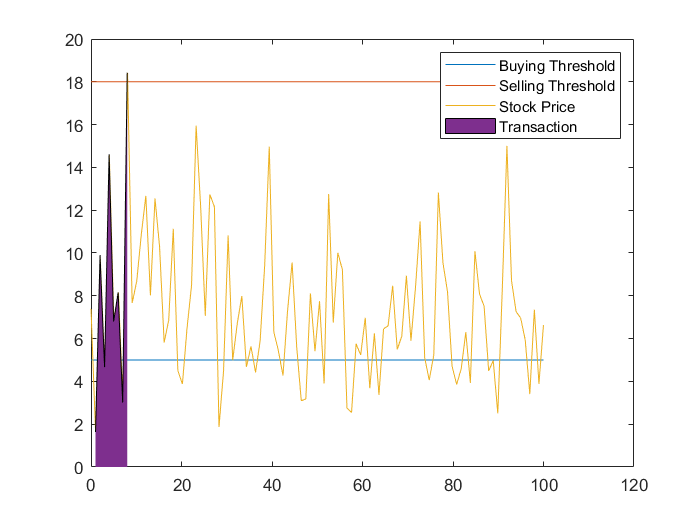

[tau_b,ColNrs] = find(stock_prices(:, 1) < b0);
[tau_s,ColNrs] = find(stock_prices(:, 1) > s0);
[tau_s,ColNrs] = min(tau_s(find(tau_s > tau_b(1))));

clf;
plot(t, ones(length(t), 1) * b0)
hold on
plot(t, ones(length(t), 1) * s0)
plot(t, stock_prices(:, 1))

one_buy_time = tau_b(1);
one_sell_time = tau_s(1);
ix = [one_buy_time: 1: one_sell_time] / N_T * T - 1;
yz = stock_prices(one_buy_time:one_sell_time, 1);
area(ix, yz)

legend("Buying Threshold", "Selling Threshold", "Stock Price", "Transaction")

disp("Total revenue before Optimization")

Total revenue before Optimization


phi = exp(-0.01 * tau_s(1) / length(stock_prices(:, 1)) * T) * s0 * (1 - 0.01) - exp(-0.01 * tau_b(1) / length(stock_prices(:, 1)) * T) * b0 * (1 + 0.01)

phi = 11.3363

## After Optimization:

What we gain using the optimized buying and selling threshold to perform one transaction on the same stock

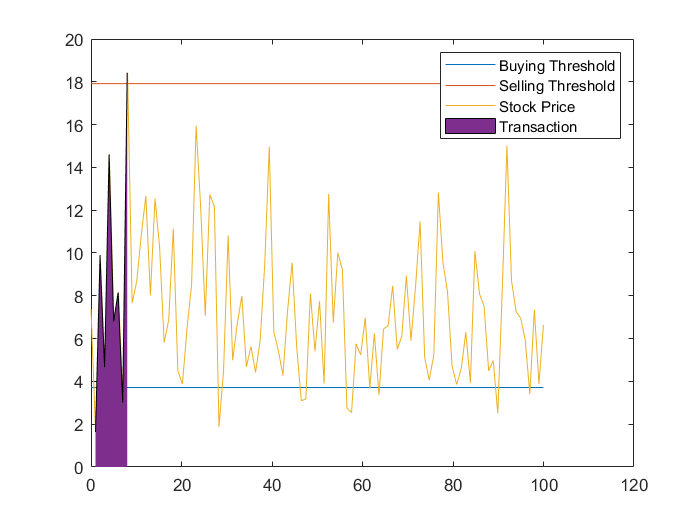

[tau_b,ColNrs] = find(stock_prices(:, 1) < b(end));
[tau_s,ColNrs] = find(stock_prices(:, 1) > s(end));
[tau_s,ColNrs] = min(tau_s(find(tau_s > tau_b(1))));

clf;
plot(t, ones(length(t), 1) * b(end))
hold on
plot(t, ones(length(t), 1) * s(end))
plot(t, stock_prices(:, 1))

one_buy_time = tau_b(1);
one_sell_time = tau_s(1);
ix = [one_buy_time: 1: one_sell_time] / N_T * T - 1;
yz = stock_prices(one_buy_time:one_sell_time, 1);
area(ix, yz)

legend("Buying Threshold", "Selling Threshold", "Stock Price", "Transaction")

disp("Total revenue after Optimization");

Total revenue after Optimization


phi = exp(-0.01 * tau_s(1) / length(stock_prices(:, 1)) * T) * s(end) * (1 - 0.01) - exp(-0.01 * tau_b(1) / length(stock_prices(:, 1)) * T) * b(end) * (1 + 0.01)

phi = 12.5340

## Following what I have thought (Local Optimization):

Use only one OU functions, but buy and sell multiple times in one period.

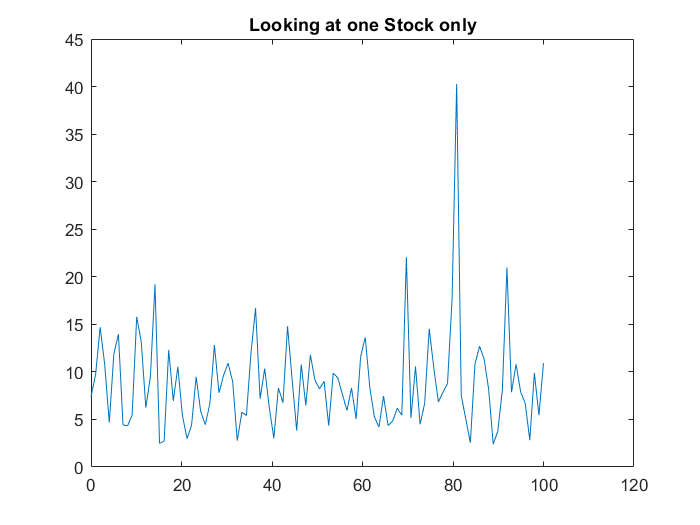

b0 = 5;
s0 = 18;
num_iter = 300;

% stock_price = stock_prices(:, randi(NSample));
stock_price = stock_prices(:, 2);

clf;
plot(t, stock_price)
title("Looking at one Stock only")
hold off

reward =    20.0442   23.5196   25.9923   24.3406   23.8947   25.4587   26.8864   25.7510   25.1416   26.3073   25.7700   25.1856   26.1951   27.1651   26.3466   25.8010   26.6752   26.2319   27.0562   26.5471   26.1320   26.8951   26.4125   27.1417   26.5103   27.2097   26.6029   26.1565   26.8174   26.3826   26.0321   26.6602   27.2784   26.7377   26.3299   26.9210   26.5964   27.1713   26.7811   27.3411   26.8488   26.4712   27.0108   26.7105   27.2377   26.8739   27.3895   26.9347   26.5813   27.0809


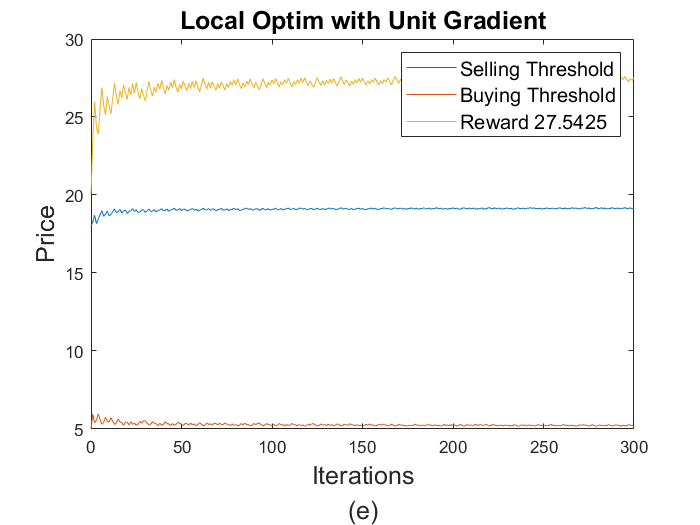

reward =    20.0442   24.9810   25.3748   25.0533   25.3318   25.0827   25.3100   25.0995   26.8370   25.1989   26.7529   25.2712   26.6899   26.8443   26.6955   26.8393   26.7000   26.8351   26.7039   26.8316   26.7071   26.8286   26.7099   26.8260   26.7123   26.8237   26.7145   26.8217   26.7164   26.8198   26.7182   26.8182   26.7197   26.8167   26.7212   26.8153   26.7225   27.5304   26.7332   27.5201   26.7431   27.5106   26.7523   27.5017   26.7608   27.4934   26.7688   27.4857   26.7764   27.4784


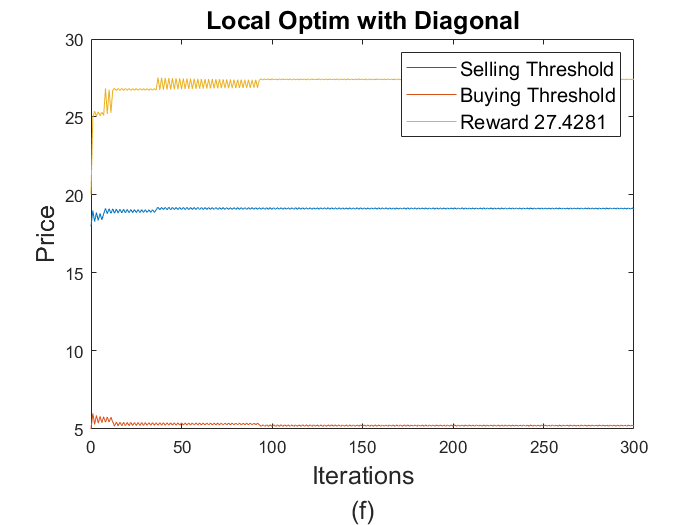

reward =    20.0442   22.8024   24.7367   23.1573   24.5251   23.3017   24.4185   23.3846   24.3517   23.4399   24.3049   23.4801   24.2698   25.0286   24.2974   25.0038   24.3199   24.9833   24.3386   24.9661   24.3544   24.9514   24.3682   24.9386   24.3802   24.9273   24.3908   24.9173   24.4003   24.9083   24.4088   24.9002   24.4166   24.8928   24.4236   24.8860   24.4301   24.8798   24.4360   24.8741   24.4416   24.8688   24.4467   24.8638   24.4514   24.8592   24.4559   24.8549   24.4601   24.8509


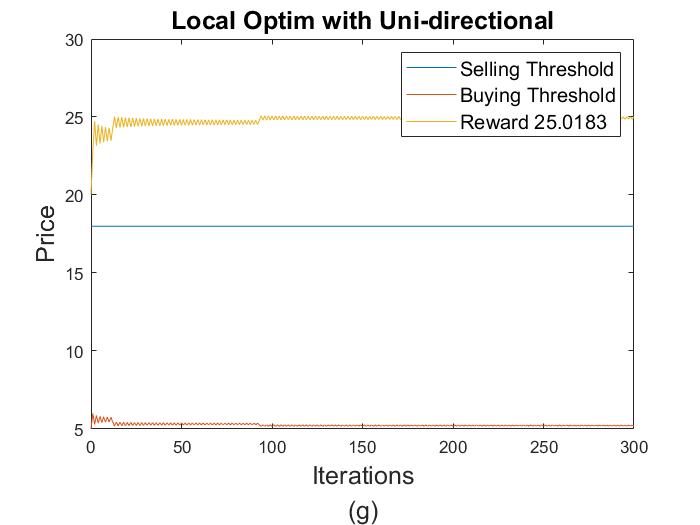


rewards = {};
s_s = {};
b_s = {};
strategis = ["Adaptive Gradient", "Unit Gradient", "Diagonal", "Uni-directional"];
x_labels = ["0", "(e)", "(f)", "(g)"];

for mode=1:3
    s = [];
    b = [];
    reward = [];
    b(1) = b0;
    s(1) = s0;
    for iter=1:num_iter
        c = (iter) ^ (-1/2);
        reward(iter) = MultiTransactionReward(stock_price, b(iter), s(iter), T);
        
        incre_b = b(iter) + c;
        reward_incre_b = MultiTransactionReward(stock_price, incre_b, s(iter), T);
        
        decre_b = b(iter) - c;
        reward_decre_b = MultiTransactionReward(stock_price, decre_b, s(iter), T);
        
        incre_s = s(iter) + c;
        reward_incre_s = MultiTransactionReward(stock_price, b(iter), incre_s, T);
        
        decre_s = s(iter) - c;
        reward_decre_s = MultiTransactionReward(stock_price, b(iter), decre_s, T);
        
        gradient_b = (reward_incre_b - reward_decre_b) / (2 * c);
        gradient_s = (reward_incre_s - reward_decre_s) / (2 * c);
        
        mag = sqrt(gradient_b ^ 2 + gradient_s ^ 2);
        
        [next_b, next_s] = update_bs(b(iter), s(iter), ...
            gradient_b, gradient_s, ...
            iter, c, mode);
        
        b(iter + 1) = next_b;
        s(iter + 1) = next_s;
        
        change = sqrt((b(iter + 1) - b(iter))^2 + (s(iter + 1)- s(iter))^2);
        if iter > 1 && change < 0.001
            break
        end
    end
    
    reward(iter + 1) = MultiTransactionReward(stock_price, b(iter + 1), s(iter + 1), T)
    
    figure()
    plot(linspace(0, length(reward) - 1, length(reward)), s)
    hold on
    plot(linspace(0, length(reward) - 1, length(reward)), b)
    plot(linspace(0, length(reward) - 1, length(reward)), reward)
    legend("Selling Threshold", "Buying Threshold", "Reward" + " " + string(reward(end)), "FontSize", 12)
    title("Local Optim with " + strategis(mode + 1), "FontSize", 15)
    hold off
    rewards{mode + 1} = reward;
    s_s{mode + 1} = s;
    b_s{mode + 1} = b;
    ylabel("Price", "FontSize", 15)
    xlabel({"Iterations", x_labels(mode + 1)}, "FontSize", 15) 
end

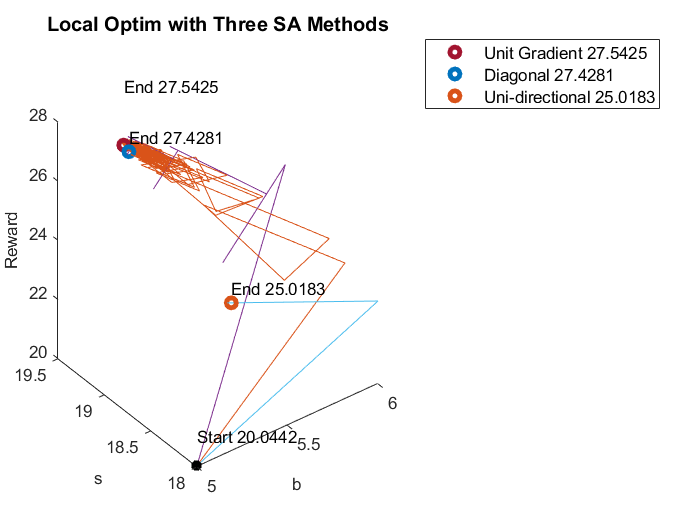

clf;
for i=2:4
    b = b_s{i};
    s = s_s{i};
    reward = rewards{i};
    plot3(b(1), s(1), reward(1), "*black", "linewidth", 3)
    hold on
    plot3(b, s, reward)
    hold on
    if i == 2
       text(b(end), s(end), reward(end) + 2, append('End ', string(reward(end)))) 
    else
       text(b(end), s(end), reward(end) + 0.5, append('End ', string(reward(end)))) 
    end
end
text(b_s{i}(1), s_s{i}(1), rewards{i}(1) + 1, append('Start ', string(rewards{i}(1))))

p = [];
for i=2:4
    b = b_s{i};
    s = s_s{i};
    reward = rewards{i};
    p(i-1) = plot3(b(end), s(end), reward(end), "o", "linewidth", 3, 'DisplayName', strategis(i) + " " + string(reward(end)));
end

xlabel("b", "FontSize", 10)
ylabel("s", "FontSize", 10)
zlabel("Reward", "FontSize", 10)
title("Local Optim with Three SA Methods", "FontSize", 12)

legend(p, "FontSize", 10)

b(end), s(end), reward(end)

ans = 5.1900

ans = 18

ans = 25.0183

## Using the inital Buying and Selling Thresholds:

Much less gross income from all transactions.

one_stock_price = stock_price;
% All this part is about finding the all possible sets of 
% buying and selling times for this given stock using the
% b0 and s0

[buy_times, sell_times] = find_set_of_selling_buying_time(one_stock_price, b0, s0); 

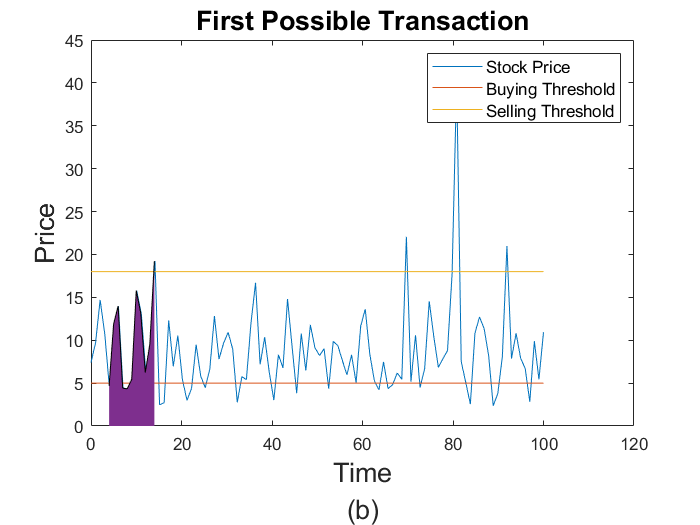

clf;
% Plot the stock price, buying & selling threshold, and 
% the transactions (shaded period)
plot(t, one_stock_price)
hold on
plot(t, ones(length(t), 1) * b0)
plot(t, ones(length(t), 1) * s0)


for i=1:1
    one_buy_time = buy_times(i);
    one_sell_time = sell_times(i);
    ix = [one_buy_time: 1: one_sell_time] / N_T * T - 1;
    yz = one_stock_price(one_buy_time:one_sell_time);
    area(ix, yz)
end

legend("Stock Price", "Buying Threshold", "Selling Threshold", "FontSize", 10)
title("First Possible Transaction", "FontSize", 16)
xlabel({"Time", "(b)"}, 'FontSize', 16)
ylabel("Price", 'FontSize', 16)
hold off

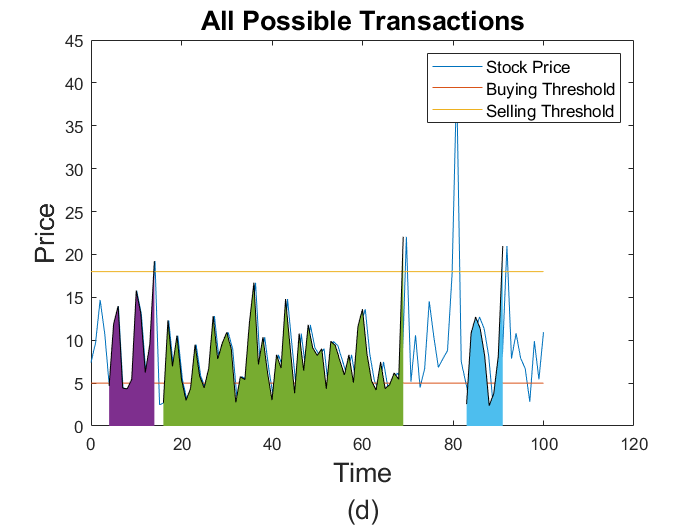

clf;
% Plot the stock price, buying & selling threshold, and 
% the transactions (shaded period)
plot(t, one_stock_price)
hold on
plot(t, ones(length(t), 1) * b0)
plot(t, ones(length(t), 1) * s0)


for i=1:length(buy_times)
    one_buy_time = buy_times(i);
    one_sell_time = sell_times(i);
    ix = [one_buy_time: 1: one_sell_time] / N_T * T - 1;
    yz = one_stock_price(one_buy_time:one_sell_time);
    area(ix, yz)
end

legend("Stock Price", "Buying Threshold", "Selling Threshold", "FontSize", 10)
title("All Possible Transactions", "FontSize", 16)
xlabel({"Time", "(d)"}, 'FontSize', 16)
ylabel("Price", 'FontSize', 16)
hold off

## Compute Revenue using the initial Threshold

% Compute the sum of gains from all possible transaction
% on this particular stock
tau_b = buy_times;
tau_s = sell_times;

phi = exp(-0.01 * tau_s / length(one_stock_price) * T) * s0 * (1 - 0.01) - exp(-0.01 * tau_b / length(one_stock_price) * T) * b0 * (1 + 0.01)

phi =    10.5341    4.5886    4.9215


disp("Total revenue before Optimization")

Total revenue before Optimization


phi = sum(phi)

phi = 20.0442

## Using the optimized Buying and Selling Thresholds:

We get a better sum of revenues from all transactions we made.

one_stock_price = stock_price;
% All this part is about finding the all possible sets of 
% buying and selling times for this given stock using the
% b and s

[buy_times, sell_times] = find_set_of_selling_buying_time(one_stock_price, b(end), s(end)); 

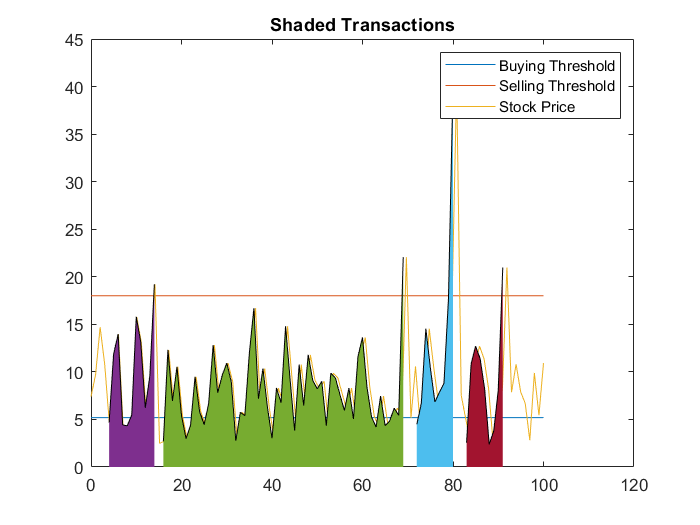

clf;
% Plot the stock price, buying & selling threshold, and 
% the transactions (shaded period)
plot(t, ones(length(t), 1) * b(end))
hold on
plot(t, ones(length(t), 1) * s(end))
plot(t, one_stock_price)

for i=1:length(buy_times)
    one_buy_time = buy_times(i);
    one_sell_time = sell_times(i);
    ix = [one_buy_time: 1: one_sell_time] / N_T * T - 1;
    yz = one_stock_price(one_buy_time:one_sell_time);
    area(ix, yz)
end

legend("Buying Threshold", "Selling Threshold", "Stock Price")
title("Shaded Transactions")
hold off

## Compute Revenue using the Optimized Threshold

% Compute the sum of gains from all possible transaction
% on this particular stock
tau_b = buy_times;
tau_s = sell_times;

phi = exp(-0.01 * tau_s / length(one_stock_price) * T) * s(end) * (1 - 0.01) - exp(-0.01 * tau_b / length(one_stock_price) * T) * b(end) * (1 + 0.01)

phi =    10.3516    4.4268    5.4013    4.8386


disp("Total revenue after Optimization")

Total revenue after Optimization


phi = sum(phi)

phi = 25.0183

## Explore the reward function on all possible '`b'` and 's':

% Explore the surface of the reward function at all possible b and s
% b and s are the x and y axes of the plot
% and the surface (z) is the reward computed at a given (b, s)
s_all = linspace(3, 23, 50);
b_all = linspace(3, 23, 50);
reward_all = [];
for i=1:length(s_all)
    for j=1:length(b_all)
        reward_all(j, i) = MultiTransactionReward(stock_price, b_all(i), s_all(j), T);
    end
end

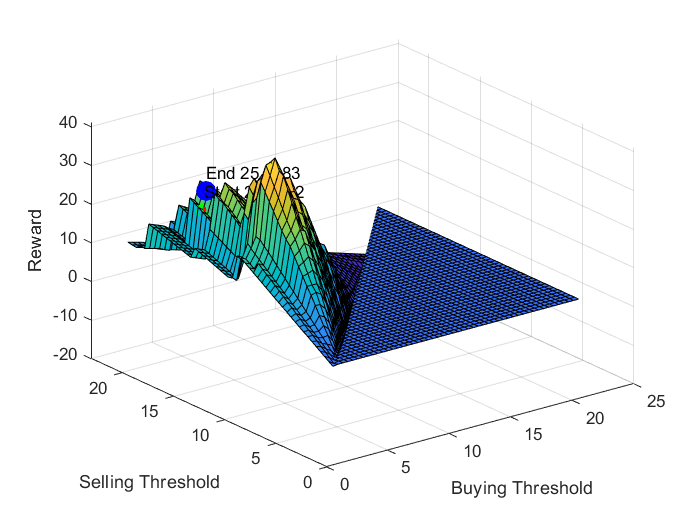

clf;
surf(b_all, s_all, reward_all)
xlabel("Buying Threshold")
ylabel("Selling Threshold")
zlabel("Reward")
%zlim([-50, 50])
hold on

plot3(b(1), s(1), reward(1), 'ogreen','linewidth',3)
plot3(b, s, reward, 'red','linewidth',2)
plot3(b(end), s(end), reward(end), 'oblue','linewidth',6)
text(b(1), s(1), reward(1) + 5, append('Start ', string(reward(1))))
text(b(end), s(end), reward(end) + 5, append('End ', string(reward(end))))
hold off

## Interactive Plot:

that shows how our algorithm are finding the local maximum of that reward function

s_all = linspace(3, 23, 500);
b_all = linspace(3, 23, 500);
reward_all = [];
for i=1:length(s_all)
    for j=1:length(b_all)
        reward_all(j, i) = MultiTransactionReward(stock_price, b_all(i), s_all(j), T);
    end
end

Interactive plot. Go to the next optimal point by pressing the key "k" on the keyboard.

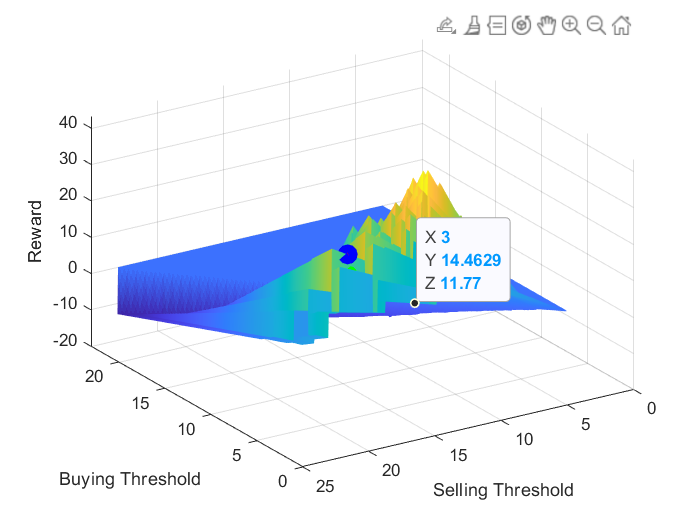

clf;
h = surf(b_all, s_all, reward_all);
set(h,'LineStyle','none')
xlabel("Buying Threshold")
ylabel("Selling Threshold")
zlabel("Reward")
hold on

plot3(b(1), s(1), reward(1), 'ogreen','linewidth',3)
step = 5;
for i=1:step:length(s)-1
    key_press = waitforbuttonpress;
    val = get(gcf, "CurrentCharacter");
    while val ~= "k"
        key_press = waitforbuttonpress;
        val = get(gcf, "CurrentCharacter");
    end
    if i ~= 1
        delete(h);
    end
    plot3(b(i:i+ step -1), s(i:i+ step -1), reward(i:i+ step -1), 'red','linewidth',2)
    h = plot3(b(i+step -1), s(i+ step -1), reward(i+ step -1), 'oblue','linewidth',3);
    hold on
end
delete(h)
plot3(b(end), s(end), reward(end), 'oblue','linewidth',6)
hold off

key_press = waitforbuttonpress

key_press = 1

val = get(gcf, "CurrentCharacter")

val = 'k'

# Function Definitions:

function [ymat, t]=EulerSystem(f, t0, y0, b, N)
    ymat = zeros(N, length(y0));
    h = (b - t0) / (N - 1);
    for i=1:length(y0)
        ymat(1, i) = y0(i);
    end
    t(1) = t0;
    for j=2:N
        for i=1:length(y0)
            ymat(j, i) = ymat(j - 1,i) + h * f{i}(t(j-1), ymat(j - 1, :));
            t(j) = t(j - 1) + h;
        end
    end
end

function [ymat, t]=RKSystem(f, t0, y0, b, N)
    ymat = zeros(N, length(y0));
    h = (b - t0) / N;
    for i=1:length(y0)
        ymat(1, i) = y0(i);
    end
    t(1) = t0;
    for j=2:N + 1
        for i=1:length(y0)
            k1 = h * f{i}(t(j-1), ymat(j - 1, :));
            k2 = h * f{i}(t(j-1) + h, ymat(j - 1, :) + k1);
            ymat(j, i) = ymat(j - 1,i) + (1 / 2) * (k1 + k2);
            t(j) = t(j - 1) + h;
        end
    end
end

function [TProcess, BProcess]=BrownMotion(sample, t0, y0, b, N)
    BProcess = [];
    TProcess = [];
    NSample = sample;
    N_T = N;
    T = b;
    
    for k = 1:NSample
        B = y0;
        t = t0;
        BProcess(1,k)=B; TProcess(1,k)=t;
        for i=2:N_T
            dt =  T/N_T;
            t = t + dt;
            B = B + sqrt(dt)*randn(1); %increments in B are normally distibuted with variance dt
            BProcess(i,k) = B;
            TProcess(i,k) = t;
        end
    end
end


function [next_b, next_s] = update_bs(b, s, gradient_b, gradient_s, ...
    iter, c, mode)
    eps =0.000001;
    % Update strategy 0 gradient vector
    if mode == 0
        next_b = b + gradient_b / iter;
        next_s = s + gradient_s / iter;
    % Update strategy 1 unit vector
    elseif mode == 1
        mag = sqrt(gradient_b ^ 2 + gradient_s ^ 2);
        
        next_b = b + gradient_b / (mag + eps) * c;
        next_s = s + gradient_s / (mag + eps) * c;
    % Update strategy 2 move in diagonal 
    elseif mode == 2
        if gradient_b > 0
            next_b = b + c;
        else
            next_b = b - c;
        end
        
        if gradient_s > 0
            next_s = s + c;
        else
            next_s = s - c;
        end
    % Update strategy 3 move in largest gradient (eithr b or s)
    elseif mode == 3
        if abs(gradient_s) > abs(gradient_b)
            next_b = b;
            if gradient_s > 0
                next_s = s + c;
            else
                next_s = s - c;
            end
        else
            next_s = s;
            if gradient_b > 0
                next_b = b + c;
            else
                next_b = b - c;
            end
        end
    end
end


% Global Optimization
% Optimize on one transaction of multiple different stock prices
function reward=TransactionReward(stock_prices, b, s, T)
    if b > s
        reward = 0;
        return
    end
    phi = [];
    for k=1:length(stock_prices(1, :))
        [tau_b,ColNrs] = find(stock_prices(:, k) < b);
        [tau_s,ColNrs] = find(stock_prices(:, k) > s);
        if length(tau_b) < 1
            continue
        end
        [tau_s,ColNrs] = min(tau_s(find(tau_s > tau_b(1))));
        if length(tau_s) < 1
            continue
        end
        tau_b = tau_b(1);
        phi(k) = exp(-0.01 * tau_s / length(stock_prices) * T) * s * (1 - 0.01) - exp(-0.01 * tau_b / length(stock_prices) * T) * b * (1 + 0.01);
    end
    
    if length(phi) < 1
        reward = 0;
    else
        reward = sum(phi) / length(stock_prices(1, :));
    end       
end


% Local Optimization
% Optimize on multiple transaction of one randomly chosen stock
function reward=MultiTransactionReward(one_stock_price, b, s, T)
    if b > s
        reward = 0;
        return
    end
    [tau_b,ColNrs] = find(one_stock_price < b);
    [tau_s,ColNrs] = find(one_stock_price > s);
    
    buy_times = [];
    sell_times = [];
    
    nth_set = 1;
    prev_s = 1;
    i = 1;
    while i <= length(tau_b)
        b_time = tau_b(i);
        s_time = 0;
        RowNrs = [];
        for j=prev_s:length(tau_s)
            if tau_s(j) > tau_b(i)
                s_time = tau_s(j);
                buy_times(nth_set) = b_time;
                sell_times(nth_set) = s_time;
                nth_set = nth_set + 1;
                prev_s = j + 1;
                
                [RowNrs,ColNrs] = find(tau_b > sell_times(end));
                if length(RowNrs) < 1 
                    break
                end
                if prev_s > length(tau_s)
                    break
                end
                i = RowNrs(1);
                break
            end
        end
        if length(RowNrs) < 1 
            break
        end
        if prev_s > length(tau_s)
            break
        end
        i = i + 1;
    end
    
    tau_b = buy_times;
    tau_s = sell_times;
    
    if length(tau_b) < 1
        reward = 0;
    else
        phi = exp(-0.01 * tau_s / length(one_stock_price) * T) * s * (1 - 0.01) - exp(-0.01 * tau_b / length(one_stock_price) * T) * b * (1 + 0.01);
        reward = sum(phi);
    end
end


function [buy_times, sell_times]=find_set_of_selling_buying_time(one_stock_price, b, s)
    [tau_b,ColNrs] = find(one_stock_price < b);
    [tau_s,ColNrs] = find(one_stock_price > s);
    
    buy_times = [];
    sell_times = [];
    
    nth_set = 1;
    prev_s = 1;
    i = 1;
    while i <= length(tau_b)
        b_time = tau_b(i);
        s_time = 0;
        
        for j=prev_s:length(tau_s)
            if tau_s(j) > tau_b(i)
                s_time = tau_s(j);
                buy_times(nth_set) = b_time;
                sell_times(nth_set) = s_time;
                nth_set = nth_set + 1;
                prev_s = j + 1;
                
                [RowNrs,ColNrs] = find(tau_b > sell_times(end));
                if length(RowNrs) < 1 
                    return
                end
                if prev_s > length(tau_s)
                    return
                end
                i = RowNrs(1);
                break
            end
        end
        i = i + 1;
    end
end